pos=randtop([6 5])

pos =     0.0113    0.9708    1.8050    2.6355    3.1175    3.7777    0.6005    1.4354    2.0642    2.6852    3.6109    4.2765         0    1.1017    1.4791    2.4562    3.2056    3.8353    0.4903    1.5369    2.2142    3.0623    3.7410    4.3524    0.0599    0.9173    1.5169    2.5055    3.1992    3.7428
    0.1089    0.4299    0.0422    0.1574         0    0.0396    0.6434    0.6817    1.1051    0.6903    0.7123    0.9229    1.4527    1.6441    1.5201    1.2955    1.4082    1.5785    2.0888    2.4123    2.2538    1.9558    2.3453    2.3123    2.8559    2.9853    2.7658    2.9408    2.6192    2.6945


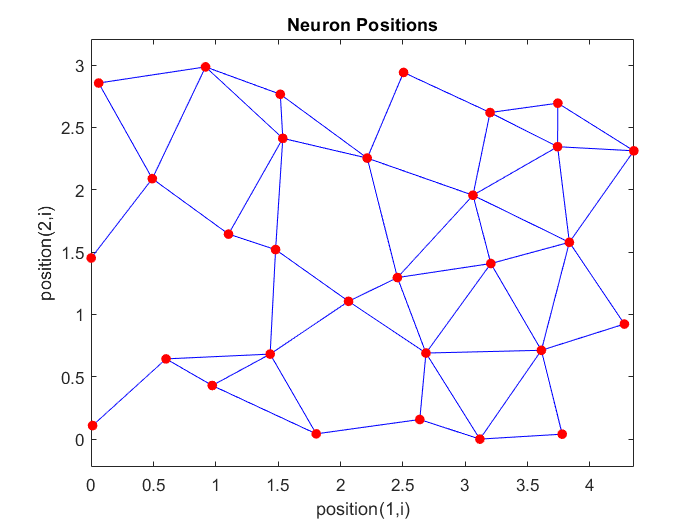

plotsom(pos)

d=linkdist(pos)

d =      0     2     3     4     5     6     1     2     3     4     5     6     6     4     3     4     5     6     5     4     5     5     6     7     6     5     5     6     6     7
     2     0     1     2     3     4     1     1     2     3     4     5     5     3     2     3     4     5     4     3     4     4     5     6     5     4     4     5     5     6
     3     1     0     1     2     3     2     1     2     2     3     4     5     3     2     3     3     4     4     3     4     4     5     5     5     4     4     5     5     6
     4     2     1     0     1     2     3     2     2     1     2     3     6     4     3     2     2     3     5     4     3     3     4     4     6     5     4     4     4     5
     5     3     2     1     0     1     4     3     2     1     1     2     6     4     3     2     2     2     5     4     3     3     3     3     6     5     4     4     4     4
     6     4     3     2     1     0     5     4     3     2     1     2     7     5     4 

net = selforgmap([2 3])


net =

    Neural Network
 
              name: 'Self-Organizing Map'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 1
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 0
        sampleTime: 1
 
    connections:
 
       biasConnect: false
      inputConnect: 

P = [.1 .3 1.2 1.1 1.8 1.7 .1 .3 1.2 1.1 1.8 1.7;...
0.2 0.1 0.3 0.1 0.3 0.2 1.8 1.8 1.9 1.9 1.7 1.8]

P =     0.1000    0.3000    1.2000    1.1000    1.8000    1.7000    0.1000    0.3000    1.2000    1.1000    1.8000    1.7000
    0.2000    0.1000    0.3000    0.1000    0.3000    0.2000    1.8000    1.8000    1.9000    1.9000    1.7000    1.8000


net =configure(net, P)


net =

    Neural Network
 
              name: 'Self-Organizing Map'
          userdata: (your custom info)
 
    dimensions:
 
         numInputs: 1
         numLayers: 1
        numOutputs: 1
    numInputDelays: 0
    numLayerDelays: 0
 numFeedbackDelays: 0
 numWeightElements: 12
        sampleTime: 1
 
    connections:
 
       biasConnect: false
      inputConnect:

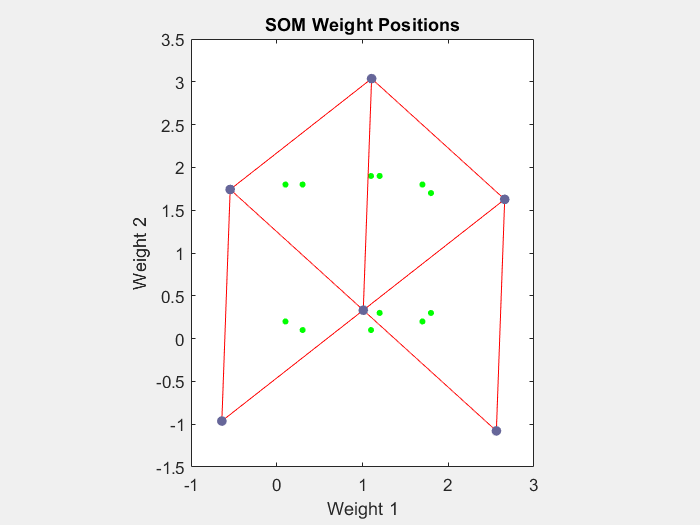

plotsompos(net,P)

m=max(P)

m =     0.2000    0.3000    1.2000    1.1000    1.8000    1.7000    1.8000    1.8000    1.9000    1.9000    1.8000    1.8000


s=min(P)

s =     0.1000    0.1000    0.3000    0.1000    0.3000    0.2000    0.1000    0.3000    1.2000    1.1000    1.7000    1.7000


l=length(P)

l = 12

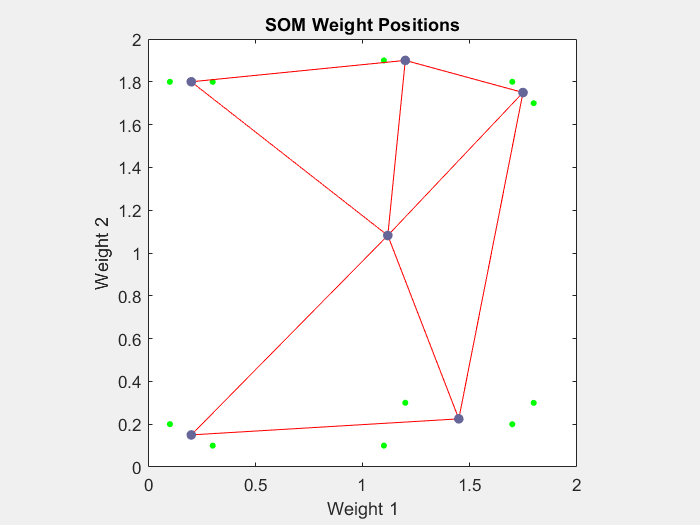

net.trainParam.epochs = 1000;
net = train(net,P);
plotsompos(net,P)